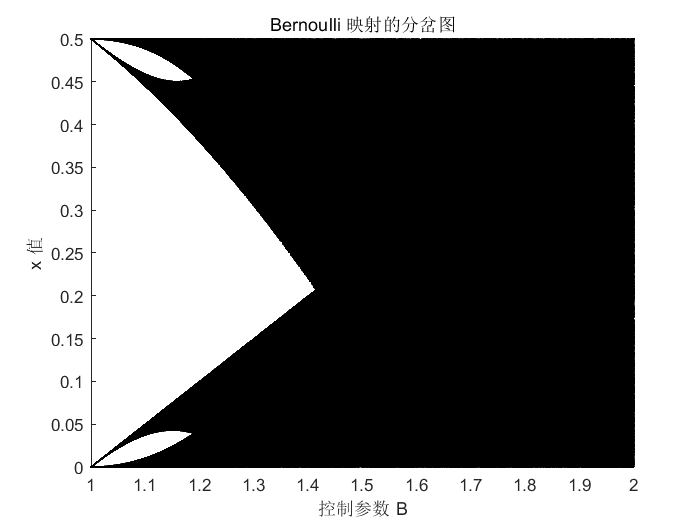

% Bernoulli 映射的分岔图
% 参数设置
B_min = 1;       % 控制参数 B 的最小值
B_max = 2;       % 控制参数 B 的最大值
num_B = 10000;    % B 的采样点数量
N = 1000;        % 总迭代次数
nSkip = 500;     % 跳过前 nSkip 次迭代，以排除初始条件的影响

% 初始化 B 的值和保存分岔图的 x 值
B_values = linspace(B_min, B_max, num_B); % B 从 B_min 到 B_max 的采样点
x_vals = zeros(num_B, N - nSkip);         % 存储分岔图中的 x 值

% 遍历每个 B 值，计算对应的 Bernoulli 映射
for i = 1:num_B
    B = B_values(i);   % 当前 B 值
    x = 0.5;           % 初始条件
    
    % 进行 N 次迭代
    for n = 1:N
        if x<0
            x=B*x+1/2; 
        else
            x=B*x-1/2;  % Bernoulli 映射公式
        end
        % 跳过前 nSkip 次迭代，保存后续的值
        if n > nSkip
            x_vals(i, n - nSkip) = x;
        end
    end
end

% 绘制分岔图
figure;
plot(B_values, x_vals, '.k', 'MarkerSize', 0.1);
xlabel('控制参数 B');ylabel('x 值');title('Bernoulli 映射的分岔图');
axis([B_min, B_max, 0, 0.5]);